## Add code and data paths

addpath(genpath('./'))
addpath(genpath('../data'))


## Create multitaper and gcoh settings

gcohparams = struct;
gcohparams.inference = 'none';
gcohparams.version = 'window';

params = struct;
params.tapers = [3 5];
params.fpass = [0 50];
params.err = [2 0.05];
params.pad = -1;
params.movingwin = [3 3];
params.Fs = Fs;


## Load data and run global coherence using gcoh_plus

Awake state (30 secs), before propofol induction

load('../data/eeganes07laplac250_detrend_all_t180.mat')
gcohout_awake = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on windows... without inference.
Computing mean across tapers... Done.
Computing eigendecompositions... Done.


Unconscious state (30 secs), low propofol dose

load('../data/eeganes07laplac250_detrend_all_t3070.mat')
gcohout_low = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on windows... without inference.
Computing mean across tapers... Done.
Computing eigendecompositions... Done.


Unconscious state (30 secs), high propofol dose

load('../data/eeganes07laplac250_detrend_all_t4710.mat')
gcohout_high = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on windows... without inference.
Computing mean across tapers... Done.
Computing eigendecompositions... Done.


## Plot power of top eigenmodes for three states

All three states have strong alpha coherence

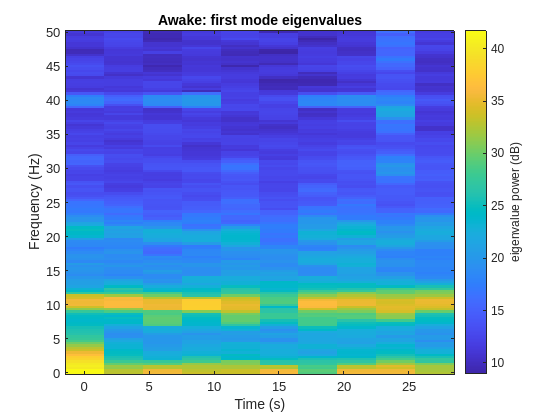

% Extract eigenvalues for the first eigenmode across frequencies and time
eigvals_awake = squeeze(gcohout_awake.eigenvalues(1,:,:));
eigvals_low = squeeze(gcohout_low.eigenvalues(1,:,:));
eigvals_high = squeeze(gcohout_high.eigenvalues(1,:,:));

% Plot the eigenvalues across frequencies and time for the first eigenmode
figure;
imagesc(gcohout_awake.times, gcohout_awake.freqs, pow2db(eigvals_awake));
axis xy
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Awake: first mode eigenvalues');
c = colorbar;
ylabel(c,'eigenvalue power (dB)')

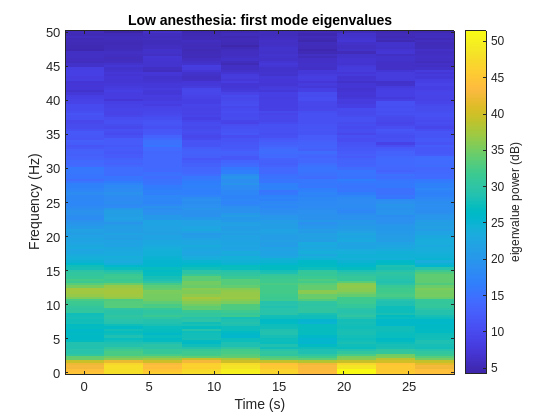


figure;
imagesc(gcohout_low.times, gcohout_low.freqs, pow2db(eigvals_low));
axis xy
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Low anesthesia: first mode eigenvalues');
c = colorbar;
ylabel(c,'eigenvalue power (dB)')

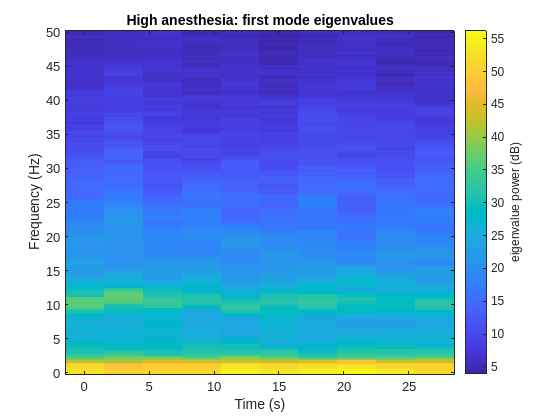


figure;
imagesc(gcohout_high.times, gcohout_high.freqs, pow2db(eigvals_high));
axis xy
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('High anesthesia: first mode eigenvalues');
c = colorbar;
ylabel(c,'eigenvalue power (dB)')

Note that all three states have global coherence (high eigenvalues in the first mode) in the alpha band.

## Plot alpha-coherent power topoplots

We will observe which channels contribute to global coherence in the first eigenmode.

Compute the coherent PSD by reconstructing the cross-spectral matrix from the 1st eigenmode.

mode = 1;

cohpower_awake = cohPSD(gcohout_awake.eigenvectors_l, gcohout_awake.eigenvalues, gcohout_awake.eigenvectors_r, mode);
cohpower_low = cohPSD(gcohout_low.eigenvectors_l, gcohout_low.eigenvalues, gcohout_low.eigenvectors_r, mode);
cohpower_high = cohPSD(gcohout_high.eigenvectors_l, gcohout_high.eigenvalues, gcohout_high.eigenvectors_r, mode);


Plot topoplots for each state. Maximize each figure in own window for visibility. (Select a plot, then click the arrow in the upper right corner, "Open in figure window". Maximize the window.)

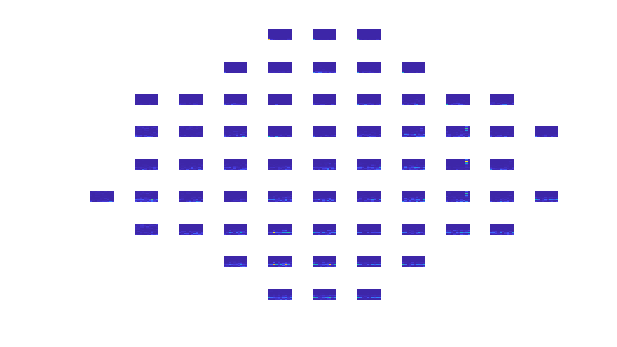

plot_cohtopo(cohpower_awake,egrid_0indexed)

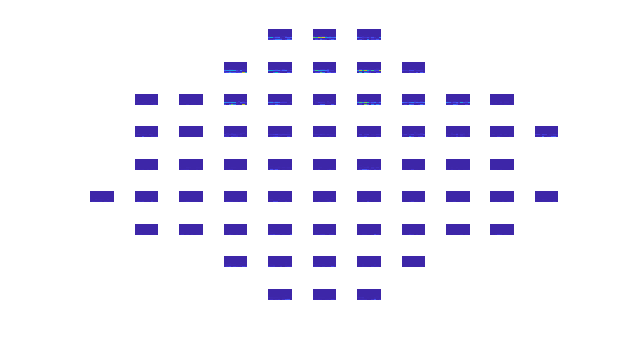

plot_cohtopo(cohpower_low,egrid_0indexed)

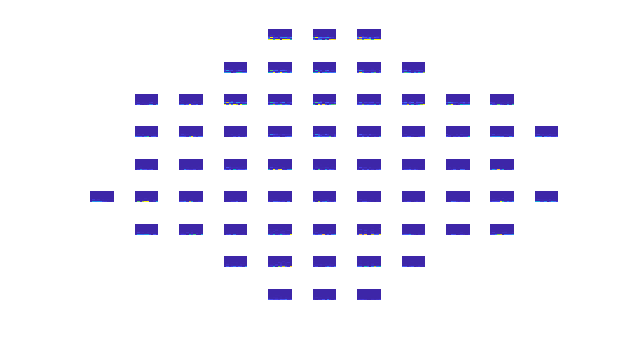

plot_cohtopo(cohpower_high,egrid_0indexed,[0 500])

## Run gcoh_plus with frequency-domain bootstrap

gcohparams = struct;
gcohparams.inference = 'fdb';
gcohparams.version = 'epoch';

load('../data/eeganes07laplac250_detrend_all_t180.mat')
gcohout_awakefdb = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on epoch(s)... with non-parametric FDB.
Computing FDB... f = 0
f = 0.33333
f = 0.66667
f = 1
f = 1.3333
f = 1.6667
f = 2
f = 2.3333
f = 2.6667
f = 3
f = 3.3333
f = 3.6667
f = 4
f = 4.3333
f = 4.6667
f = 5
f = 5.3333
f = 5.6667
f = 6
f = 6.3333
f = 6.6667
f = 7
f = 7.3333
f = 7.6667
f = 8
f = 8.3333
f = 8.6667
f = 9
f = 9.3333
f = 9.6667
f = 10
f = 10.3333
f = 10.6667
f = 11
f = 11.3333
f = 11.6667
f = 12
f = 12.3333
f = 12.6667
f = 13
f = 13.3333
f = 13.6667
f = 14
f = 14.3333
f = 14.6667
f = 15
f = 15.3333
f = 15.6667
f = 16
f = 16.3333
f = 16.6667
f = 17
f = 17.3333
f = 17.6667
f = 18
f = 18.3333
f = 18.6667
f = 19
f = 19.3333
f = 19.6667
f = 20
f = 20.3333
f = 20.6667
f = 21
f = 21.3333
f = 21.6667
f = 22
f = 22.3333
f = 22.6667
f = 23
f = 23.3333
f = 23.6667
f = 24
f = 24.3333
f = 24.6667
f = 25
f = 25.3333
f = 25.6667
f = 26
f = 26.3333
f = 26.6667
f = 27
f = 27.3333
f = 27.6667
f = 28
f = 28.3333
f = 28.6667
f = 29
f = 29.


load('../data/eeganes07laplac250_detrend_all_t3070.mat')
gcohout_lowfdb = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on epoch(s)... with non-parametric FDB.
Computing FDB... f = 0
f = 0.33333
f = 0.66667
f = 1
f = 1.3333
f = 1.6667
f = 2
f = 2.3333
f = 2.6667
f = 3
f = 3.3333
f = 3.6667
f = 4
f = 4.3333
f = 4.6667
f = 5
f = 5.3333
f = 5.6667
f = 6
f = 6.3333
f = 6.6667
f = 7
f = 7.3333
f = 7.6667
f = 8
f = 8.3333
f = 8.6667
f = 9
f = 9.3333
f = 9.6667
f = 10
f = 10.3333
f = 10.6667
f = 11
f = 11.3333
f = 11.6667
f = 12
f = 12.3333
f = 12.6667
f = 13
f = 13.3333
f = 13.6667
f = 14
f = 14.3333
f = 14.6667
f = 15
f = 15.3333
f = 15.6667
f = 16
f = 16.3333
f = 16.6667
f = 17
f = 17.3333
f = 17.6667
f = 18
f = 18.3333
f = 18.6667
f = 19
f = 19.3333
f = 19.6667
f = 20
f = 20.3333
f = 20.6667
f = 21
f = 21.3333
f = 21.6667
f = 22
f = 22.3333
f = 22.6667
f = 23
f = 23.3333
f = 23.6667
f = 24
f = 24.3333
f = 24.6667
f = 25
f = 25.3333
f = 25.6667
f = 26
f = 26.3333
f = 26.6667
f = 27
f = 27.3333
f = 27.6667
f = 28
f = 28.3333
f = 28.6667
f = 29
f = 29.


load('../data/eeganes07laplac250_detrend_all_t4710.mat')
gcohout_highfdb = gcoh_plus(y, [], params, gcohparams);

Computing multitaper cross-spectrum... Done.
Running gcoh on epoch(s)... with non-parametric FDB.
Computing FDB... f = 0
f = 0.33333
f = 0.66667
f = 1
f = 1.3333
f = 1.6667
f = 2
f = 2.3333
f = 2.6667
f = 3
f = 3.3333
f = 3.6667
f = 4
f = 4.3333
f = 4.6667
f = 5
f = 5.3333
f = 5.6667
f = 6
f = 6.3333
f = 6.6667
f = 7
f = 7.3333
f = 7.6667
f = 8
f = 8.3333
f = 8.6667
f = 9
f = 9.3333
f = 9.6667
f = 10
f = 10.3333
f = 10.6667
f = 11
f = 11.3333
f = 11.6667
f = 12
f = 12.3333
f = 12.6667
f = 13
f = 13.3333
f = 13.6667
f = 14
f = 14.3333
f = 14.6667
f = 15
f = 15.3333
f = 15.6667
f = 16
f = 16.3333
f = 16.6667
f = 17
f = 17.3333
f = 17.6667
f = 18
f = 18.3333
f = 18.6667
f = 19
f = 19.3333
f = 19.6667
f = 20
f = 20.3333
f = 20.6667
f = 21
f = 21.3333
f = 21.6667
f = 22
f = 22.3333
f = 22.6667
f = 23
f = 23.3333
f = 23.6667
f = 24
f = 24.3333
f = 24.6667
f = 25
f = 25.3333
f = 25.6667
f = 26
f = 26.3333
f = 26.6667
f = 27
f = 27.3333
f = 27.6667
f = 28
f = 28.3333
f = 28.6667
f = 29
f = 29.

## Plot global coherence spectrum for all three states

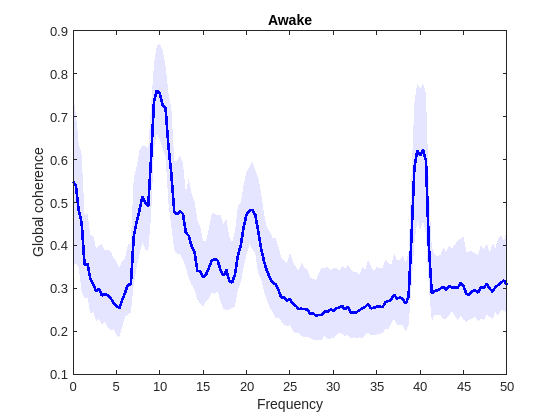

plot_gcoh(gcohout_awakefdb.eigenvalues, gcohout_awakefdb.freqs);
title(gca,'Awake')

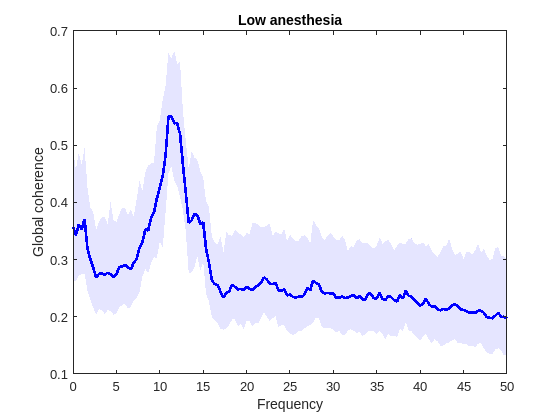

plot_gcoh(gcohout_lowfdb.eigenvalues, gcohout_lowfdb.freqs);
title(gca,'Low anesthesia')

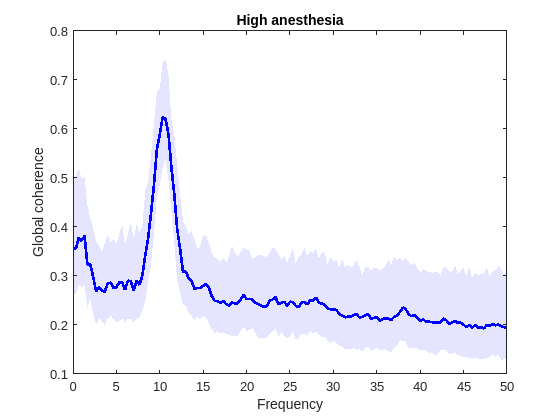

plot_gcoh(gcohout_highfdb.eigenvalues, gcohout_highfdb.freqs);
title(gca,'High anesthesia')

Observe the coherent harmonics in the awake data that appear absent in the anesthesia states, as well as some line noise at 40 Hz.

## Plot angular distances within and between states

Compute distances between bootstrap iterations

[~, alpha_i] = min(abs(gcohout_awakefdb.freqs - 10));

disp('Computing distances within states')

Computing distances within states


angmat_prepre = angdist_boot(gcohout_awakefdb.eigenvectors_r, gcohout_awakefdb.eigenvectors_r, 1);
angmat_lowlow = angdist_boot(gcohout_lowfdb.eigenvectors_r, gcohout_lowfdb.eigenvectors_r, 1);
angmat_highhigh = angdist_boot(gcohout_highfdb.eigenvectors_r, gcohout_highfdb.eigenvectors_r, 1);

disp('Computing distances between states')

Computing distances between states


angmat_lowhigh = angdist_boot(gcohout_lowfdb.eigenvectors_r, gcohout_highfdb.eigenvectors_r, 1);
angmat_prelow = angdist_boot(gcohout_awakefdb.eigenvectors_r, gcohout_lowfdb.eigenvectors_r, 1);
angmat_prehigh = angdist_boot(gcohout_awakefdb.eigenvectors_r, gcohout_highfdb.eigenvectors_r, 1);


Plot angular distances across frequencies within states

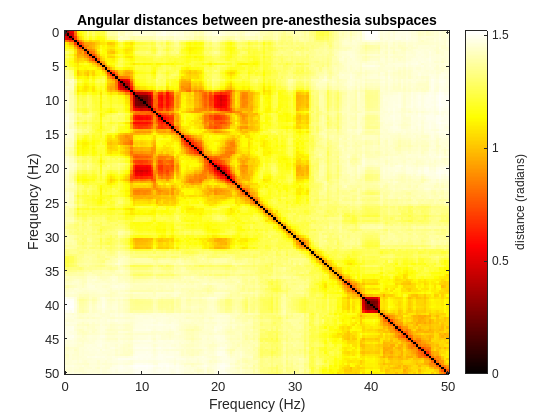

freqs = gcohout_awakefdb.freqs;

figure;
imagesc(freqs, freqs, mean(angmat_prepre,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between pre-anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

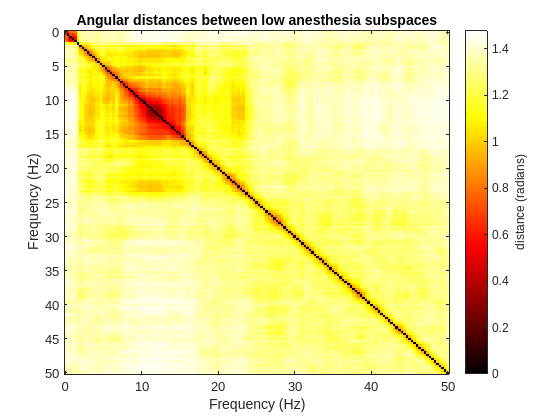


figure;
imagesc(freqs, freqs, mean(angmat_lowlow,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between low anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

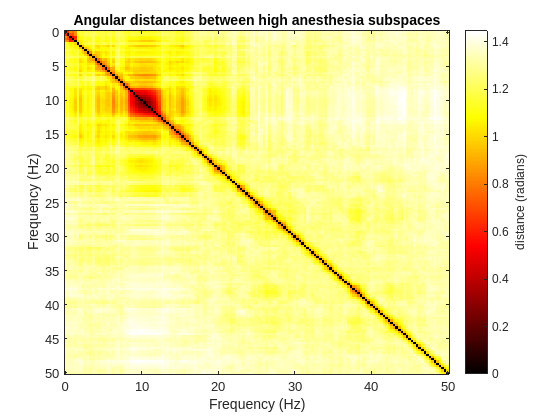


figure;
imagesc(freqs, freqs, mean(angmat_highhigh,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between high anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

Plot angular distances between states across frequencies

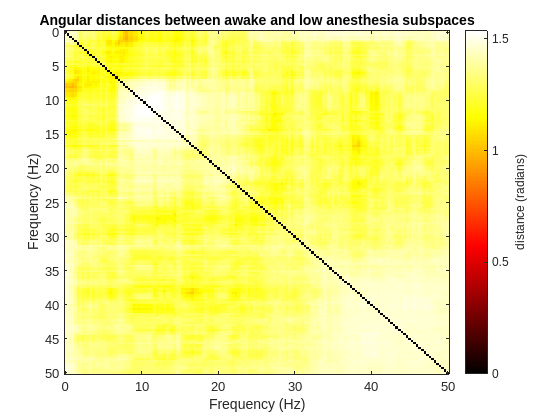

figure;
imagesc(freqs, freqs, mean(angmat_prelow,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between awake and low anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

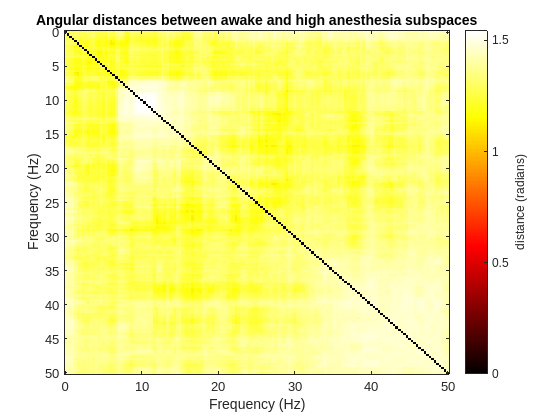


figure;
imagesc(freqs, freqs, mean(angmat_prehigh,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between awake and high anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

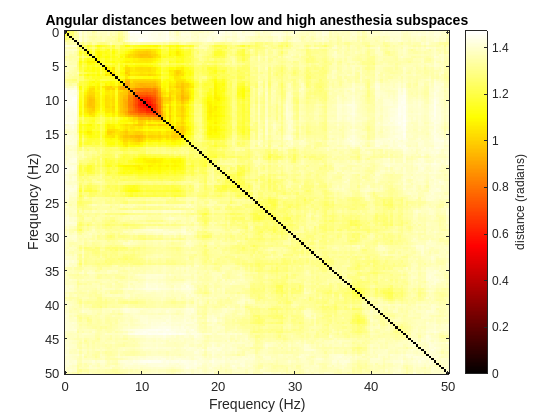


figure;
imagesc(freqs, freqs, mean(angmat_lowhigh,3))
colormap hot
xlabel('Frequency (Hz)')
ylabel('Frequency (Hz)')
title('Angular distances between low and high anesthesia subspaces')
c = colorbar;
ylabel(c,'distance (radians)')

## Subfunctions

Create a function to plot each channels' cohereograms in a topographically defined grid.

function plot_cohtopo(cohpower, egrid_0indexed, f_i, clim_set)
    %PLOTPSD Plot power spectral density (PSD) for all channels
    %
    % This function plots the PSD for each channel as a subplot in a grid.
    % The position of each subplot is determined by the indices in egrid_0indexed.
    %
    % Inputs:
    %    PSD - The power spectral density matrix, size: N_channels x N_freqs x N_windows.
    %    egrid_0indexed - An array whose elements are the indices of PSD, with rows and
    %                     columns corresponding to the final figure grid, 0 indexed.
    %
    % Outputs: none
    %
    % Example:
    %    output = gcoh_plus(data, epochs, mtparams, gcohparams);
    %    Pxy = recon_mtx(output.eigenvectors_l, output.eigenvalues, output.eigenvectors_r);
    %    PSD = cohPSD(output.eigenvectors_l, output.eigenvalues, output.eigenvectors_r);
    %    plotPSD(PSD, egrid_0indexed);

    if ~exist('f_i','var') || isempty(f_i)
        clim_set = [1:size(cohpower,2)];
    end

    if ~exist('clim_set','var') || isempty(clim_set)
        clim_set = [];
    end
    
    % Add 1 to 0 indexed array
    egrid = egrid_0indexed + 1;
    
    % Get grid size
    [gridSizeY, gridSizeX] = size(egrid);

    figure('units','normalized','outerposition',[0 0 1 1])
    
    % Loop over each channel
    for chIdx = 1:size(cohpower, 1)
        
        % Find position of current channel in egrid
        [posY, posX] = find(egrid == chIdx);
        
        % Create subplot at the appropriate grid position
        subplot(gridSizeY, gridSizeX, (posY-1)*gridSizeX + posX);
        
        % imagesc the PSD of the current channel
        imagesc(squeeze(cohpower(chIdx, :, :)));
        if ~isempty(clim_set)
            clim(gca,[clim_set])
        end
        
        axis off
        axis xy
    end
    
    % Add a colorbar and adjust its position to not overlap with the subplots
    h = colorbar;
    set(h, 'Position', [.92 .11 .0281 .8150])
    
end


Create a function that plots the global coherence spectrum.

function plot_gcoh(eigenvalues, freqs)
    
    eigenvalues = real(eigenvalues);
    
    % Compute the variance explained by the first mode
    var_explained = squeeze(eigenvalues(1,:,:)) ./ squeeze(sum(eigenvalues, 1));
    
    % Compute the mean across windows
    mean_var_explained = mean(var_explained, 2);
        
    % Compute 5th and 95th percentiles of the bootstrap samples
    lower_bound = prctile(var_explained', 5, 1);
    upper_bound = prctile(var_explained', 95, 1);
    
    % Generate x values
    x = freqs;
    
    % Create the fill coordinates
    X_fill = [x; flipud(x)];
    Y_fill = [upper_bound'; fliplr(lower_bound)'];
    
    
    figure;
    % Plot the fill area
    fill(X_fill, Y_fill, 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    hold on
    
    % plot the mean 
    plot(freqs, mean_var_explained, 'b', 'LineWidth', 2); 
    
    xlabel('Frequency');
    ylabel('Global coherence');

end
